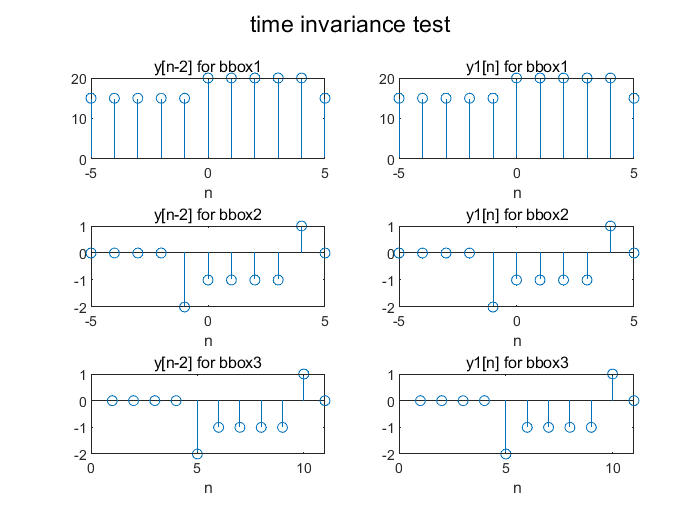

clear;
% time invariance test
n=-5:5;
% let x denote x[n], x1 denote x1[n]=x[n-n0]
% let y[n], y1[n] denote the outputs of x[n] and x1[n]
% check y[n-n0]=y1[n]
x=[zeros(1,3) ones(1,5) zeros(1,3)];%input
x1=[zeros(1,5) ones(1,5) 0];% set n0=2
nhead=-7:5;%find the new element after the right shifting
xhead=[zeros(1,2) x];
yahead=bbox1(xhead);yahead=yahead(1:2);
ybhead=bbox2(xhead);ybhead=ybhead(1:2);
ychead=bbox3(xhead);ychead=ychead(1:2);
ya=bbox1(x); ya_delay=[yahead ya(1:length(ya)-2)]; ya1=bbox1(x1);
yb=bbox2(x); yb_delay=[ybhead yb(1:length(yb)-2)]; yb1=bbox2(x1);
yc=bbox3(x); yc_delay=[ychead yc(1:length(yc)-2)]; yc1=bbox3(x1);
sgtitle('time invariance test')
orient('tall')
% bbox1
subplot(321),stem(n,ya_delay),title('y[n-2] for bbox1'),xlabel('n');
subplot(322),stem(n,ya1),title('y1[n] for bbox1'),xlabel('n');
% bbox2
subplot(323),stem(n,yb_delay),title('y[n-2] for bbox2'),xlabel('n');
subplot(324),stem(n,yb1),title('y1[n] for bbox2'),xlabel('n');
% bbox3
subplot(325),stem(yc_delay),title('y[n-2] for bbox3'),xlabel('n');
subplot(326),stem(yc1),title('y1[n] for bbox3'),xlabel('n');